# Main script

Within this file, everything you need to find and evaluate your magnetic field can be found! Make sure to modify values where it's suggested, and to only run the blocks you need!

## Determine magnetic moment of dipoles

Simulate the magnetic field which arises from a collection of ideal magnetic dipoles, and determine how their magnetization should be set to achieve a target magnetic profile.

### Set general parameters

%% Here, specify where all dipoles are located. These position must me
% explicitly specified. Each row corresponds to a dipole, and its columns
% are x, y and z positions.
dipole_positions = dipole_array(linspace(-2, 2, 3), linspace(-2, 2, 3), [-1 1]);

% Now, for each dipole, specify its magnetic moment. Every row should
% relate to the magnetic moment of the dipole of the same row in
% 'dipole_positions'. Set values to 'nan' to indicate that the values
% should be determined by a target field.
dipole_M = repmat([0, 0, nan], height(dipole_positions), 1);

% Here, specify on which domain to evaluate the B-field. Currently, only
% discs normal to the z-axis are available
target_domain = struct('Origin', [0,0,0], 'R', 1, 'Phi', pi/4);

% Finally, specify the target magnetic field profile. Any undetermined dipole
% magnetizations will be set to approximate this field, on a 2D-domain
% defined above.
target_field_elementwise = B_field_linear_x(target_domain, 1);

### Set computational parameters

These parameters only affect the computational accuracy, not the problem statement

%% Ö
collision_threshold = 0.01;

### Compute stuff

Now, let the magic happen! 

%% Check if any dipole is situated exactly in the evaluation area 
dipole_in_domain = false;
% Use line below (but fix it plz) if you're really worried about this
% any(dipole_positions(:, 3) == target_domain.Z)

threshold = collision_threshold * dipole_in_domain;

% Create function from degrees-of-freedom to magnetization:
n = sum(isnan(dipole_M), 'all');
get_M = @(x) insert_params(x, dipole_M);

% Create function handle which returns a vector-type field computator from
% params x
B_func_from_x = @(x) B_function(@(xvar, X, Y, Z) get_field(X, Y, Z, dipole_positions, get_M(xvar), threshold), x);

% Create a reference field computator handle
B_0 = B_function(@(~, X, Y, Z) cell2mat(arrayfun(@(x, y, z) reshape(target_field_elementwise(x, y, z), [1 1 3]), X, Y, Z, 'UniformOutput', false)));

% Create an inner product evaluator, with information about evaluation
% domain.
inprod = inner_product(target_domain.R, target_domain.Origin, target_domain.Phi);

% GO!!!
[x, B_best] = granny_smith(B_func_from_x, B_0, inprod, n, true);

Starting to compute inner product between 1 and 1
It took 0.017957 s
Starting to compute inner product between 2 and 1
It took 0.048231 s
Starting to compute inner product between 2 and 2
It took 0.011986 s
Starting to compute inner product between 3 and 1
It took 0.019907 s
Starting to compute inner product between 3 and 2
It took 0.021971 s
Starting to compute inner product between 3 and 3
It took 0.013567 s
Starting to compute inner product between 4 and 1
It took 0.032169 s
Starting to compute inner product between 4 and 2
It took 0.031026 s
Starting to compute inner product between 4 and 3
It took 0.032097 s
Starting to compute inner product between 4 and 4
It took 0.012231 s
Starting to compute inner product between 5 and 1
It took 0.045223 s
Starting to compute inner product between 5 and 2
It took 0.037101 s
Starting to compute inner product between 5 and 3
It took 0.03251 s
Starting to compute inner product between 5 and 4
It took 0.057495 s
Starting to compute inner product b

### Plotting the result

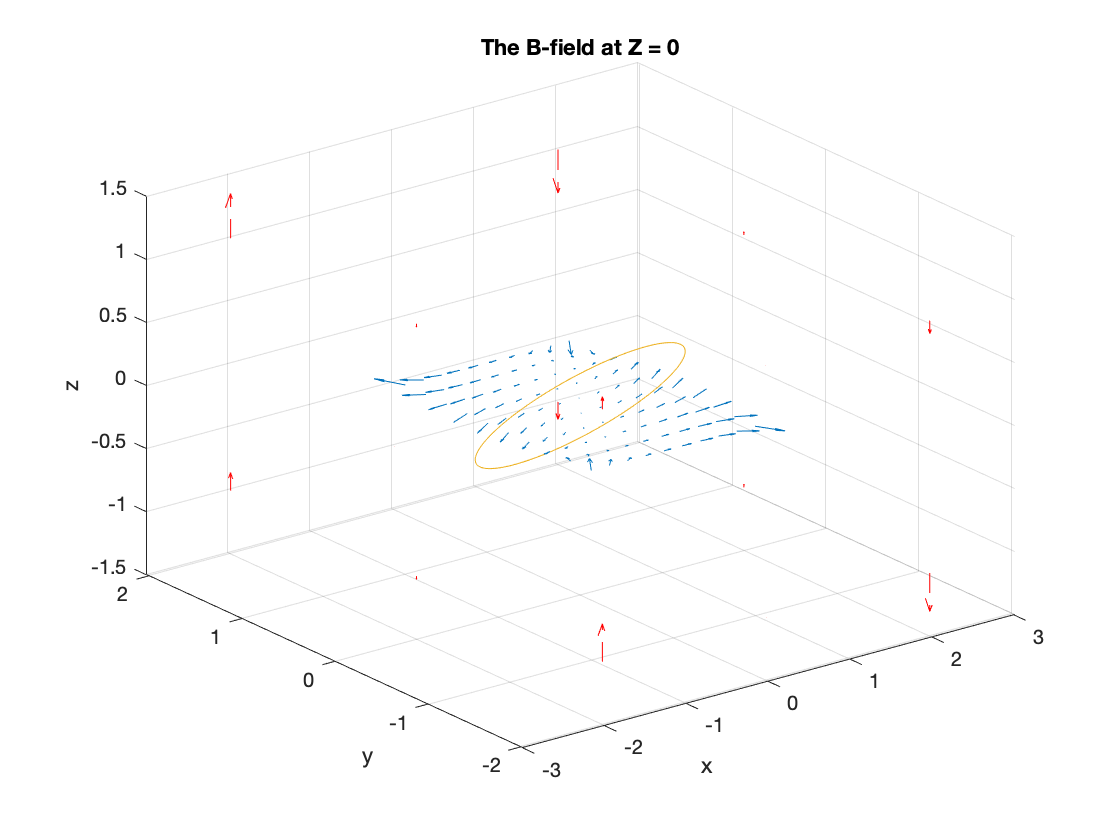

%% Select the amount of discretization points
N = 10;

% Select the boundaries of the domain
Xmax = 1;
Ymax = 1;
Z_value = 0;

% Create the mesh
[X,Y,Z] = meshgrid(linspace(-Xmax,Xmax,N),...
    linspace(-Ymax,Ymax,N),Z_value);

% Assigns the B-field and shows the quiver plot
B = B_best(X,Y,Z);

m = get_M(x);
phi = target_domain.Phi;

theta = 0:2*pi/500:2*pi;
x_circ = target_domain.R*cos(theta)';
y_circ = target_domain.R*sin(theta)';
z_circ = zeros(size(y_circ));
R_circ = [x_circ,y_circ,z_circ];

b_plot(X,Y,Z,B,Z_value,dipole_positions,m,R_circ,phi)